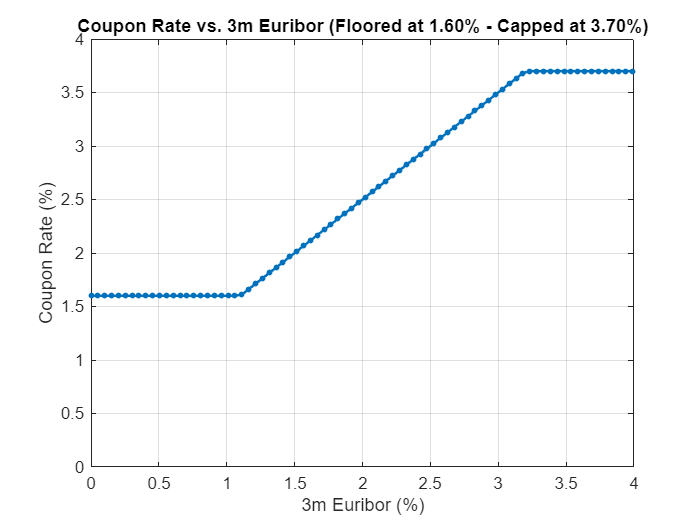

% Define Euribor rates (x-axis)
euribor_rates = linspace(0, 5, 100); % From 0% to 5% with 100 points

% Define coupon rate formula (y-axis) with floor and cap
spread = 0.5; % Assume a spread of 0.5% over Euribor
coupon_rates = euribor_rates + spread;

% Apply floor and cap
floor_rate = 1.60; % 1.60%
cap_rate = 3.70;   % 3.70%
coupon_rates = max(coupon_rates, floor_rate);
coupon_rates = min(coupon_rates, cap_rate);

% Plot the curve
figure;
plot(euribor_rates, coupon_rates, 'o-', 'MarkerSize' ,2, 'LineWidth', 1.5);
xlabel('3m Euribor (%)');
ylabel('Coupon Rate (%)');
title('Coupon Rate vs. 3m Euribor (Floored at 1.60% - Capped at 3.70%)');
grid on;
xlim([0 4]);
ylim([0 4]);
exportgraphics(gca, 'coupon-behaviour.pdf', 'ContentType', 'vector', 'Resolution', 300);